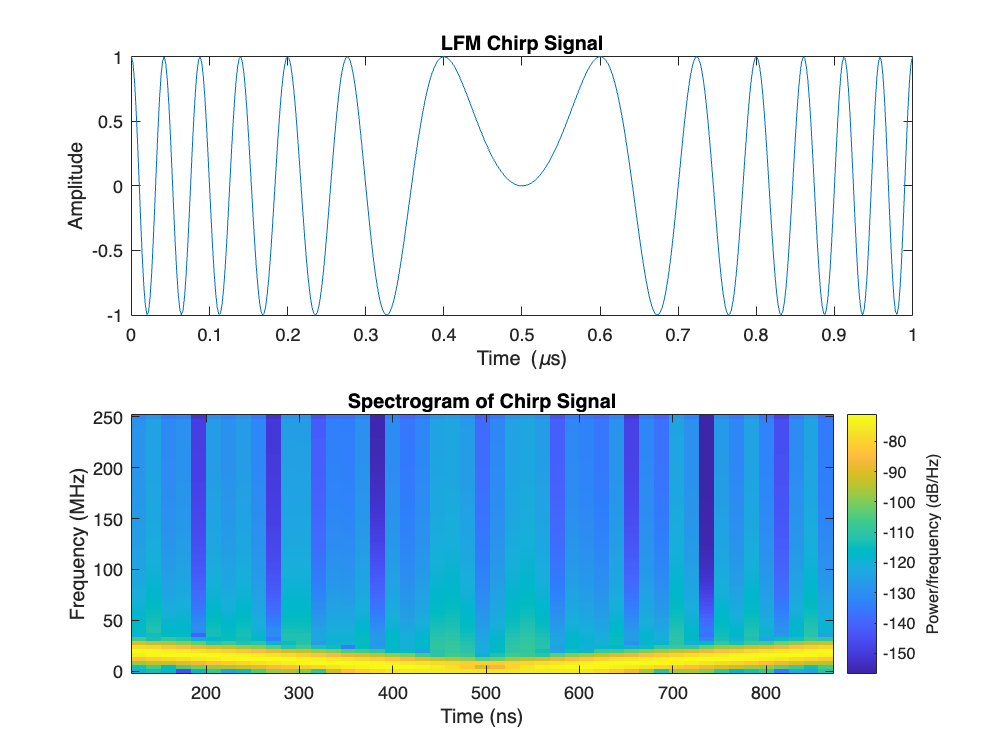

% parameters
fc = 5e9;
c = 3e8;
bw = 50e6;
prf = 1e3;
t_pulse = 1e-6;
fs = 10*bw;
r_max = c / (2*prf);
t = 0:1/fs:t_pulse;

chirp_signal = chirp(t, fc-bw/2, t_pulse, fc+bw/2);

% plot signal
figure;
subplot(2,1,1);
plot(t*1e6, real(chirp_signal));
xlabel('Time (\mus)'); ylabel('Amplitude'); title('LFM Chirp Signal');
subplot(2,1,2);
spectrogram(chirp_signal, 128, 120, 128, fs, 'yaxis');
title('Spectrogram of Chirp Signal');

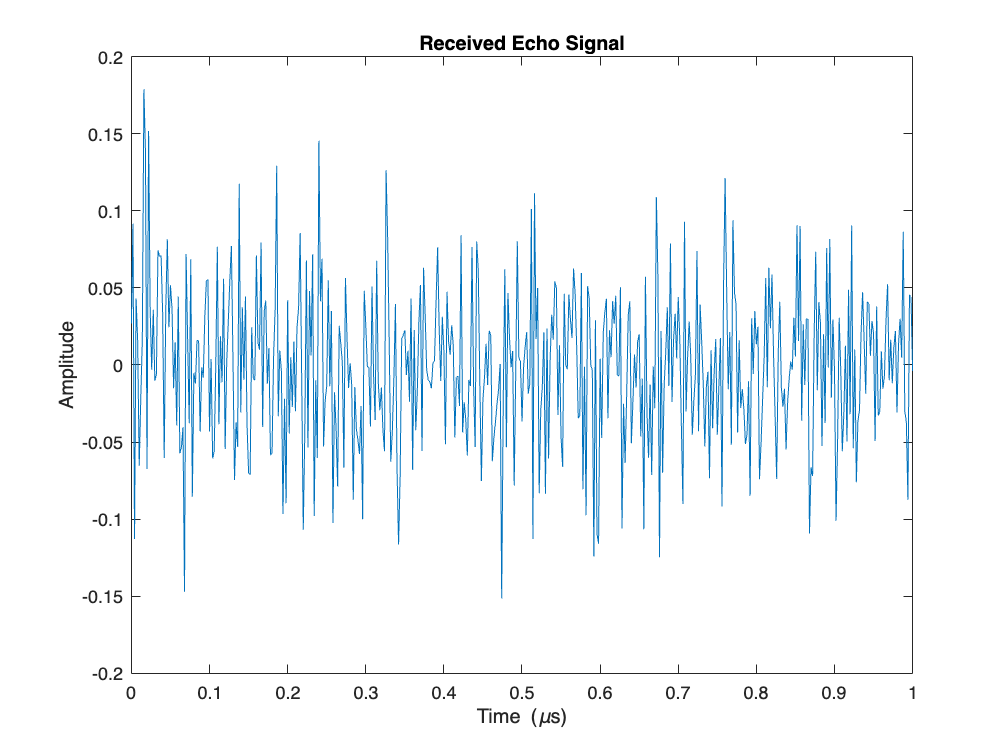


% targets
targets = [500, 1000, 1500]; % distance (m)
num_targets = length(targets);
attenuation = [0.8, 0.6, 0.4]; % reflection

delays = 2*targets / c;

% generate signal
rx_signal = zeros(size(t));
for i = 1:num_targets
    delayed_signal = [zeros(1, round(delays(i)*fs)), chirp_signal * attenuation(i)];
    delayed_signal = delayed_signal(1:length(t)); % truncate
    rx_signal = rx_signal + delayed_signal;
end

% noise
rx_signal = rx_signal + 0.05*randn(size(rx_signal));

% plot
figure;
plot(t*1e6, real(rx_signal));
xlabel('Time (\mus)'); ylabel('Amplitude');
title('Received Echo Signal');

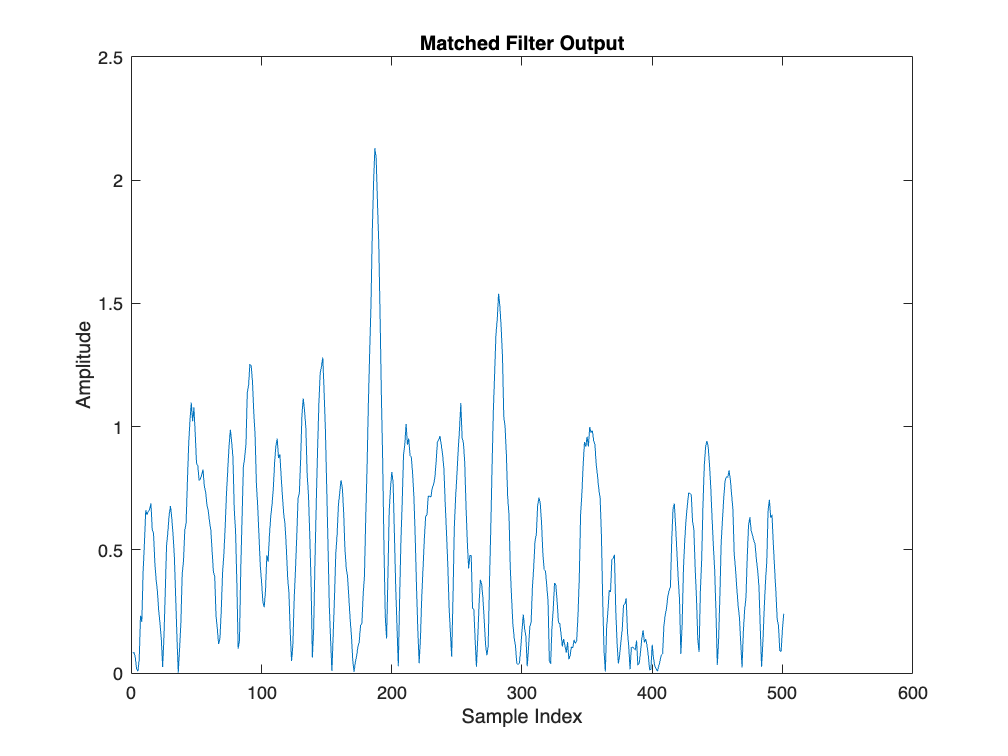


% matched filtering
matched_filter_output = conv(rx_signal, fliplr(conj(chirp_signal)), 'same');

% mf output
figure;
plot(abs(matched_filter_output));
xlabel('Sample Index'); ylabel('Amplitude');
title('Matched Filter Output');


% peaks in mfo
[pks, locs] = findpeaks(abs(matched_filter_output), 'MinPeakHeight', max(abs(matched_filter_output))/2);


range_estimates = (locs/fs) * (c/2);
disp('Estimated Target Ranges:');

Estimated Target Ranges:


disp(range_estimates);

   13.8000   14.4000   27.3000   39.6000   44.1000   56.1000   75.9000   84.6000



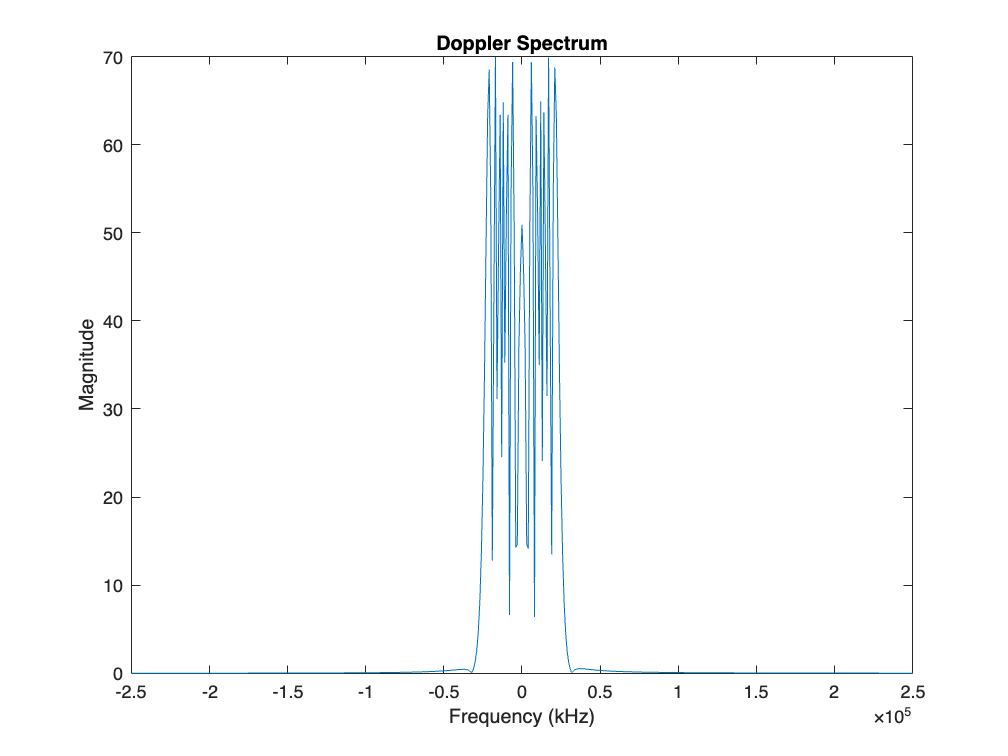


% doppler shift
v_target = 50; % v (m/s)
fd = 2*v_target*fc/c; % doppler shift formula
doppler_signal = chirp_signal .* exp(1j*2*pi*fd*t);

% fft detection
doppler_fft = fftshift(fft(doppler_signal));
freq_axis = linspace(-fs/2, fs/2, length(doppler_fft));

% doppler spectrum
figure;
plot(freq_axis/1e3, abs(doppler_fft));
xlabel('Frequency (kHz)'); ylabel('Magnitude');
title('Doppler Spectrum');